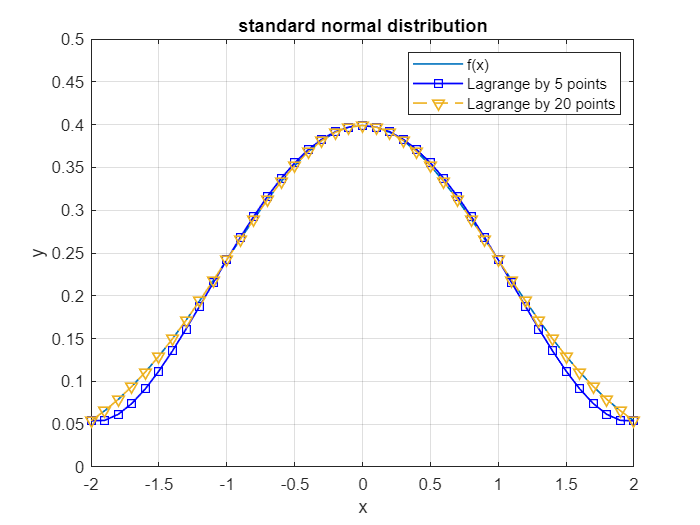

f = @(x) (1 / sqrt(2 * pi)) * exp(-(x.^2/2));
fx = [-2:.1:2];
y = f(fx);



f1 = @(x) (1 / sqrt(2 * pi)) * exp(-(x.^2/2));
datx = [-2:1:2];
daty = f1(datx);
count = 0;
LY = 0;
LY = NaN(1,length(fx));
for i = -2 : .1 : 2
    count = count + 1;
    LY(count) = Lagrange(datx, daty, i);
end
datx = [-2:.1:2];
daty = f1(datx);
count = 0;
LLY = 0;
LLY = NaN(1,length(fx));
for i = -2 : .1 : 2
    count = count + 1;
    LLY(count) = Lagrange(datx, daty, i);
end

plot(fx,y,fx, LY,'-bs',fx, LLY,'--v','LineWidth', 1);
title('standard normal distribution');
legend('f(x)','Lagrange by 5 points', 'Lagrange by 20 points');
xlabel('x');
ylabel('y');
grid on;
ylim([0.00 .5])